# Ejercicio 3

clearvars; clear all;

Creamos los patrones distribuidos:

- En una región cuadrada: `rands`

- En cuatro grupos separables: `generar_grupos `(función personalizada)

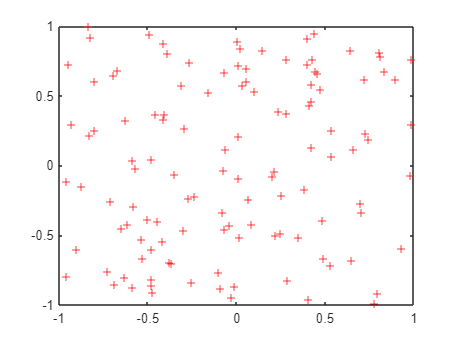

conj1 = rands(2,120);
conj2 = generar_grupos([-1 1; -1 1], 4, 80, 0.12);

% Plot values
figure();
plot(conj1(1,:), conj1(2,:), '+r');

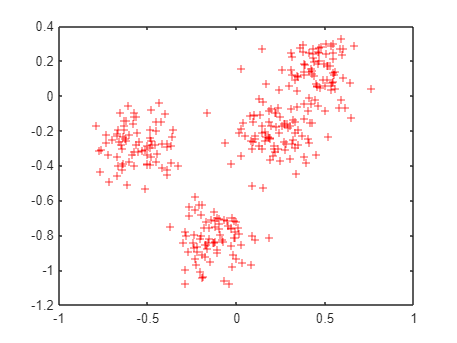

figure();
plot(conj2(1,:), conj2(2,:), '+r');

## Apartado A)

Diseñamos redes neuronales autoorganizadas donde las neuronas estén dispuestas con topología de vecindad uni-dimensional.

redA = selforgmap([5 5]);
redA.trainParam.epochs = 100;
redA.layers.topologyFcn = {'gridtop'};
red1A = train(redA, conj2);
%red2A = train(redA, conj2);